serialportlist

ans = "COM3"


baudrate = 256000;
% data_in = zeros();

s = serialport("COM3",baudrate)

s =   Serialport - 属性:

                 Port: "COM3"
             BaudRate: 256000
    NumBytesAvailable: 0

  Show all properties, functions




data = read(s,4*102400,'uint8');
% configureTerminator(s,"CR")  
% configureCallback(s,"terminator",@serial_callback) 
% configureCallback(s,"byte",1 ,@serial_callback)
% pause 
% data_serial = zeros()

if (s.NumBytesAvailable == 0)
    disp("Data reading from Serial Port Ready!")
end

Data reading from Serial Port Ready!


## 串口数据后处理


% 将uint8 -> dec 
% data_origin = dec2bin(s.UserData); 
data_origin = dec2bin(data);
% data_tag = data_origin(:,1:2);
% 
% 
% if (sum(mod(find(data_tag=='11'), 4)) == 1024 )
%     disp("Data Missing!");
%     index = find(data_tag == '11');
%     index_mod = mod(index, 4);
%     fprintf("Missing data occured at %d sampled point;\n",find(index_mod ~= 0, 3))
%     
% else
%     disp("Data Right!");
% end
clear s;
data_sign = str2num(data_origin(:,1));
data_value = data_origin(:,2:end);

data_sign(data_sign==1) = -1;
data_sign(data_sign==0) = 1;
data_value = bin2dec(data_value) .* data_sign;

N_Sample = length(data_value) / 4;
data_N4 = reshape(data_value, [4, N_Sample])'

data_N4 =     -1    15     1    -7
     1   -16     6     2
    -1    15     1    -6
     1   -16     7    -5
    -1    15     1    -7
     1   -16     7    -6
    -1    15     0     5
     1   -16     7    -3
    -1    15     0     5
     1   -16     7    -3


## Calibration

% ~~~~~~~~~~~~~~~ test environment ~~~~~~~~~~~~~~~
% clk_50M = 50E6;
% clk_adc = clk_50M / 5_000 ;
% fs = clk_adc / 50;

Vref = 1.8;
N_SUB = 5;
LSB_SUB = Vref / 2^N_SUB;

% ~~~~~~~~~~~~~~~ calculate gain ~~~~~~~~~~~~~~~
% gain = zeros(1,N_Sample);
% for i = 1:N_Sample
%     if (mod(i, 2) == 0)
%         gain_temp = Newton_Calib(-1*data_N4(i,2:end), 10);
%         gain(i) = gain_temp(10);
%     else 
%         gain_temp = Newton_Calib(data_N4(i,2:end), 10);
%         gain(i) = gain_temp(10);
%     end
% end

% Newton_Calib(data_N4(1,2:end) - data_N4(2,2:end), 10)
gain = deltaGain(data_N4(:,2:end), 10);

% gain = abs(gain);
% GAIN = mean(gain);
% % ~~~~~~~~~~~~~~~ display result ~~~~~~~~~~~~~~~
% figure
% hold on;
% plot(gain);
% % plot(gain_plus);
% plot(ones([1,N_Sample/2])*GAIN)
% % plot(ones([1,N_Sample/2])*GAIN_PLUS)
% hold off;
% xlim([0, N_Sample/2]);
% 
% legend(["LSB calibraion", "-LSB average"], ...
%     'Location', 'northeast')
% xlabel("Sample Point");
% ylabel("Gain with Calibration");
% 
% 


% ~~~~~~~~~~~~~~~ display result ~~~~~~~~~~~~~~~
% gain_min = abs(gain(1:2:end));
% gain_plus = abs(gain(2:2:end));

GAIN = mean(gain)

GAIN = 15.3119

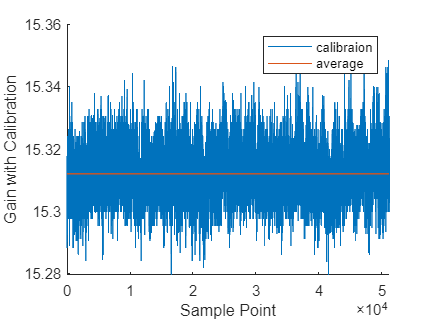




figure
hold on;
plot(gain);
plot(ones([1,N_Sample/2])*GAIN)
hold off;
xlim([0, N_Sample/2]);

legend(["calibraion", ...
    "average"], ...
    'Location', 'northeast')
xlabel("Sample Point");
ylabel("Gain with Calibration");

% 
% subplot(2,1,2)
% hold on;
% plot(gain_plus);
% plot(ones([1,N_Sample/4])*GAIN_PLUS)
% hold off;
% xlim([0, N_Sample/4]);
% 
% legend(["+LSB calibration",...
%      "+LSB average"], ...
%     'Location', 'northeast')
% xlabel("Sample Point");
% ylabel("Gain with Calibration");